% Read the table into MATLAB 
ICPMS_42 = readtable('S4-2_Simplified.csv');
% Set a text vector for the labels on the X-axis 
elemental_symbols = {'Li', 'Na', 'Mg', 'Al', 'P', 'K', 'Ca', 'Sc', 'Ti', 'Cr', 'Mn', 'Fe', 'Ni', 'Cu', 'Zn', 'Ge', 'Rb', 'Sr', 'Y', 'Zr', 'Nb', 'Ba', 'La', 'Ce', 'Pr', 'Nd', 'Sm', 'Eu', 'Gd', 'Tb', 'Dy', 'Ho', 'Er', 'Tm', 'Yb', 'Lu', 'Hf', 'U'};
% Some blank cells in data, standardize all blanks to NaN
ICPMS_42_clean = standardizeMissing(ICPMS_42, '');
% Now create vectors of each row of Mass change data for plotting 
% This is generally the same blueprint as the enrichment factors graph
% Plotting format slightly different 
%Table2array
S42_Subsite1 = ICPMS_42_clean(65,:);
Subsite1 = table2array(S42_Subsite1);
S42_Subsite2 = ICPMS_42_clean(66,:);
Subsite2 = table2array(S42_Subsite2);
S42_Subsite3 = ICPMS_42_clean(67,:);
Subsite3 = table2array(S42_Subsite3);
S42_Subsite4 = ICPMS_42_clean(68,:);
Subsite4 = table2array(S42_Subsite4);
S42_Subsite5 = ICPMS_42_clean(69,:);
Subsite5 = table2array(S42_Subsite5);
S42_Subsite6 = ICPMS_42_clean(70,:);
Subsite6 = table2array(S42_Subsite6);
S42_Subsite7 = ICPMS_42_clean(71,:);
Subsite7 = table2array(S42_Subsite7);
S42_Subsite8 = ICPMS_42_clean(72,:);
Subsite8 = table2array(S42_Subsite8);
% Data gathered, now we remove outliers
% Play around with this depending on how your raw data looks 
Subsite5 = rmoutliers(Subsite5)

Subsite5 =   -94.2029  -96.6163  -94.0810  -91.9976       NaN       NaN  -94.5909    0.0000   -0.9405  -96.6396  -96.1910  -92.0731  -95.1710  -94.8568       NaN  394.9192  -41.5212  232.8145  179.0257    9.1746  -59.4074  -39.0804  101.2433   36.3776       NaN       NaN       NaN  310.4589  100.5548       NaN   93.1290       NaN       NaN  354.1513   54.1069


Subsite6 = rmoutliers(Subsite6)

Subsite6 =   -97.8206  -96.7545  -97.9751  -93.2410  -99.4258   19.0639  -82.8717  -91.1186   -0.0000  -79.0373  -98.6348  -98.5191  -98.7766  -99.5952  -97.7028       NaN   17.8182    1.7258  442.5604   22.9504   19.3725   36.2422  287.7800  359.0657  285.9308       NaN  425.2061       NaN       NaN       NaN       NaN       NaN  360.0668       NaN   69.1297


Subsite7 = rmoutliers(Subsite7)

Subsite7 =   -60.6549  -98.9487  -65.0026  -84.7460       NaN  -24.9354  -33.5456  -90.8718    0.0000  -83.1797  -68.6092  -67.3262  -28.7177  -96.8072  -37.6407       NaN  -36.2681  -30.4847   20.2681  -85.1785   40.0620   -8.2818  -31.5202  -36.3397  -33.6048  -22.5880  -65.3926   34.2584  -31.1978  -64.6078  -16.5246       NaN   70.5324       NaN  -43.4499   -2.7307


Subsite8 = rmoutliers(Subsite8)

Subsite8 =   -97.2128  -99.8886  -96.5376  -98.4356  -99.9418  -53.7543  -91.9949  -98.4225    0.0000  -78.2612  -97.0903  -96.5727  -94.2156  -99.5618  -95.8093  -98.1279  -61.0928  -82.2366  -82.4736  -50.4797       NaN       NaN       NaN       NaN  -63.2079  -57.2727       NaN       NaN       NaN       NaN  -49.1241


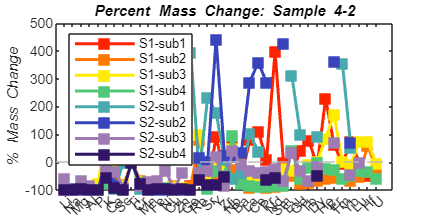

%Plot
figure('Position', [100, 100, 1000, 500])
% First subsite, hold on to the rest
plot(Subsite1, '-s','Linewidth', 1.5, Color='#FF2400', MarkerFaceColor='#FF2400')
hold on;
% Filled squares connected by a line with hexcode colors 
plot(Subsite2, '-s', 'Linewidth', 1.5, Color='#FF7900', MarkerFaceColor='#FF7900')
plot(Subsite3, '-s','Linewidth', 1.5, Color='#FFEA00',  MarkerFaceColor='#FFEA00')
plot(Subsite4, '-s', 'Linewidth', 1.5, Color='#50C878', MarkerFaceColor='#50C878')
plot(Subsite5, '-s', 'Linewidth', 1.5, Color='#48AAAD', MarkerFaceColor='#48AAAD')
plot(Subsite6, '-s', 'Linewidth', 1.5, Color='#3944BC', MarkerFaceColor='#3944BC')
plot(Subsite7, '-s', 'Linewidth', 1.5, Color='#9E7BB3', MarkerFaceColor='#9E7BB3')
plot(Subsite8, '-s', 'Linewidth', 1.5, Color='#311465', MarkerFaceColor='#311465')
yline(0, '--r', 'LineWidth', 1, Color = '#B8B8B8');
% Legend for each subsite
legend('S1-sub1', 'S1-sub2','S1-sub3','S1-sub4','S2-sub1','S2-sub2','S2-sub3','S2-sub4', Location='Northwest')
% Sets an x axis for the elements without mismatching array sizes due to
% removed outliers 
xticks(1:length(elemental_symbols));
xticklabels(elemental_symbols);
xtickangle(45); 
set(gca, 'FontSize', 7);
ylabel('\it% Mass Change')
title('\itPercent Mass Change: Sample 4-2')
hold off;

% Calculating Volume Strain (Chen et al., 2024)
% Calculations involve density of original/unaltered rock
% Alongside 1/ Enrichment factor of reference species
% Selected reference species is Ti in this case 


% Mineralogy - Fraction of quartz, muscovite by site spot
% S1QO = Site 1, quartz in original (microlithon)
% S1MA = Site 1, muscovite in altered (inseam) 
S1QO = 1;
S1MO = 0;
S1QA = 0;
S1MA = 1;
S2QO = 1;
S2MO = 0;
S2QA = .10;
S2MA = .90;
AvgQO = 1;
AvgMO = 0;
AvgQA = .05;
AvgMA = .95;
% Densities (g/mL)
rho_qtz = 2.65;
rho_musc = 2.83;
% Calculate densities of original, altered rock 
S1_rho_org = (S1QO*rho_qtz)+(S1MO*rho_musc);
S1_rho_alt = (S1QA*rho_qtz)+(S1MA*rho_musc);
S2_rho_org = (S2QO*rho_qtz)+(S2MO*rho_musc);
S2_rho_alt = (S2QA*rho_qtz)+(S2MA*rho_musc);
Avg_rho_alt = (AvgQA*rho_qtz)+(AvgMA*rho_musc);
Avg_rho_org = (AvgQO*rho_qtz)+(AvgMO*rho_musc);

% Existing values in sample 4-2, 1/EF (Ti)
% CoCa = Concentration Ti original / concentration Ti altered 

%AVERAGES 
CoCaS1 = .025733591;
CoCaS2 = .018033541;
CoCaAvg = .021113561;

%INDIVIDUAL PAIRS 
    CoCaS1_1 = .011564339;
    CoCaS1_2 = .045057224;
    CoCaS1_3 = .042063866;
    CoCaS1_4 = .004248934;
    CoCaS2_1 = .027270725;
    CoCaS2_2 = 0.010818539;
    CoCaS2_3 = 0.023130866;
    CoCaS2_4 = 0.003213982;

% Calculate Volume strain 
% ((Co/Ca)*(rho_org/rho_alt))-1
 
%AVERAGES 

    %VolS1 = ((CoCaS1)*(S1_rho_org/S1_rho_alt))-1;
    %VolS2 = ((CoCaS2)*(S2_rho_org/S2_rho_alt))-1;
    %VolAvg = ((CoCaAvg)*(Avg_rho_org/Avg_rho_alt))-1;

%INDIVIDUAL PAIRS 
    VolS1_1 = ((CoCaS1_1)*(Avg_rho_org/Avg_rho_alt))-1

VolS1_1 = -0.9891

    VolS1_2 = ((CoCaS1_2)*(Avg_rho_org/Avg_rho_alt))-1

VolS1_2 = -0.9577

    VolS1_3 = ((CoCaS1_3)*(Avg_rho_org/Avg_rho_alt))-1

VolS1_3 = -0.9605

    VolS1_4 = ((CoCaS1_4)*(Avg_rho_org/Avg_rho_alt))-1

VolS1_4 = -0.9960

    VolS2_1 = ((CoCaS2_1)*(Avg_rho_org/Avg_rho_alt))-1

VolS2_1 = -0.9744

    VolS2_2 = ((CoCaS2_2)*(Avg_rho_org/Avg_rho_alt))-1

VolS2_2 = -0.9898

    VolS2_3 = ((CoCaS2_3)*(Avg_rho_org/Avg_rho_alt))-1

VolS2_3 = -0.9783

    VolS2_4 = ((CoCaS2_4)*(Avg_rho_org/Avg_rho_alt))-1

VolS2_4 = -0.9970

    
% Try volume gain/loss with Naiobium reference species 

% Calculate strain rates using fisher, hirth flow law
% Check Tsaiwei's chart, do a Kernel density function 
% Calculate vol strain for all paio
% Track proportion of sites with x volume loss (kdf)
% Normalize probability (y axis)
% X axis is volume strain
% Use volume strain calculations for each pair
% Apply to fisher, Hirth flow laws to get a range of strain rates
% Then get time range 


